% The purpose of this code is to implement the Safe Flight Corridors and
% Receding Horizon Path Planning Algorithm
% The authors of this code are: Christian Chang, Christopher Poole, Trevor Rizzo and Diana
% Lee Guzman


### Process Overview

### Map Generation

### Path Planning

### Path Analysis

### Planner Analysis

iterations = [1;2;3;4;5;6;7;8;9;10];

%Time Elapsed sfc
time_elapsed_sfc_grid1 = [1;3;2;5;4;7;6;9;10;8];
time_elapsed_sfc_grid2 = [1;2;3;4;5;6;7;8;9;10];

%Time elapsed RRT
time_elapsed_rrt_grid1 = [1;10;9;8;7;5;4;3;2;1];
time_elapsed_rrt_grid2 = [10;9;8;7;6;10;9;4;5;6];

%Path Distance SFC
path_distance_sfc_grid1 = [1;3;2;5;4;7;6;9;10;8];
path_distance_sfc_grid2 = [1;2;3;4;5;6;7;8;9;10];

%Path Distance RRT
path_distance_rrt_grid1 = [1;10;9;8;7;5;4;3;2;1];
path_distance_rrt_grid2 = [10;9;9;7;6;10;9;4;5;6];

%Nodes Visited SFC
nodes_visited_sfc_grid1 = [1;3;2;5;4;7;6;9;10;8];
nodes_visited_sfc_grid2 = [1;2;3;4;5;6;7;8;9;10];

%Nodes Visited RRT
nodes_visited_rrt_grid1 = [1;10;9;8;7;5;4;3;2;1];
nodes_visited_rrt_grid2 = [10;9;8;7;6;10;9;4;5;6];

%Roboustness SFC
robustness_sfc_grid1 = [1; 1; 0; 1; 1; 0; 1; 1; 1; 1];
robustness_sfc_grid2 = [1; 1; 0; 1; 1; 0; 1; 1; 1; 1];

%Roboustness RRT
robustness_rrt_grid1 = [1; 0; 0; 1; 1; 0; 1; 0; 1; 0];
robustness_rrt_grid2 = [1; 0; 0; 1; 1; 0; 1; 0; 1; 0];

%Variables for pass/fail ratio
[pass_rrt, fail_rrt, pass_sfc, fail_sfc] = deal(0, 0, 0, 0);

for i = 1:10
    if robustness_rrt_grid1(i,1) == 1
        pass_rrt = pass_rrt + 1;
    else
        fail_rrt = fail_rrt +1;
    end
    if robustness_rrt_grid2(i,1) == 1
        pass_rrt = pass_rrt + 1;
    else
        fail_rrt = fail_rrt +1;
    end
    
    if robustness_sfc_grid1(i,1) == 1
        pass_sfc = pass_sfc + 1;
    else
        fail_sfc = fail_sfc +1;
    end
    if robustness_sfc_grid2(i,1) == 1
        pass_sfc = pass_sfc + 1;
    else
        fail_sfc = fail_sfc +1;
    end
end

%Grab rows & columns
[r1,c1] = size(robustness_sfc_grid1);
[r2,c2] = size(robustness_sfc_grid2);
[r3,c3] = size(robustness_rrt_grid1);
[r4,c4] = size(robustness_rrt_grid2);

%Pass/Fail Ratios
sfc_pass = pass_sfc / (c1 + c2);
sfc_fail = fail_sfc / (c1 + c2);
rrt_pass = pass_rrt / (c1 + c2);
rrt_fail = fail_rrt / (c1 + c2);

%Table
T = table(time_elapsed_sfc_grid1, time_elapsed_rrt_grid1, path_distance_sfc_grid1, path_distance_rrt_grid1, nodes_visited_sfc_grid1, nodes_visited_rrt_grid1, robustness_sfc_grid1, robustness_rrt_grid1)

T = 10×8 table
    time_elapsed_sfc_grid1    time_elapsed_rrt_grid1    path_distance_sfc_grid1    path_distance_rrt_grid1    nodes_visited_sfc_grid1    nodes_visited_rrt_grid1    robustness_sfc_grid1    robustness_rrt_grid1
    ______________________    ______________________    _______________________    _______________________    _______________________    _______________________    ____________________    ____________________

               1                         1                         1                          1                          1                          1                        1                       1          
               3                        10                         3                 

T = table(time_elapsed_sfc_grid2, time_elapsed_rrt_grid2, path_distance_sfc_grid2, path_distance_rrt_grid2, nodes_visited_sfc_grid2, nodes_visited_rrt_grid2, robustness_sfc_grid2, robustness_rrt_grid2)

T = 10×8 table
    time_elapsed_sfc_grid2    time_elapsed_rrt_grid2    path_distance_sfc_grid2    path_distance_rrt_grid2    nodes_visited_sfc_grid2    nodes_visited_rrt_grid2    robustness_sfc_grid2    robustness_rrt_grid2
    ______________________    ______________________    _______________________    _______________________    _______________________    _______________________    ____________________    ____________________

               1                        10                         1                         10                          1                         10                        1                       1          
               2                         9                         2                 

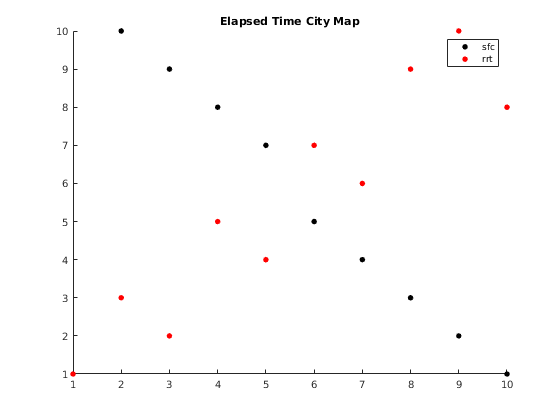


%Figure 1: Elapsed Time City Map
scatter(iterations,time_elapsed_rrt_grid1, "black", "filled")
hold on;
scatter(iterations,time_elapsed_sfc_grid1, "red", "filled")
title ("Elapsed Time City Map")
legend('sfc', 'rrt');

hold off;

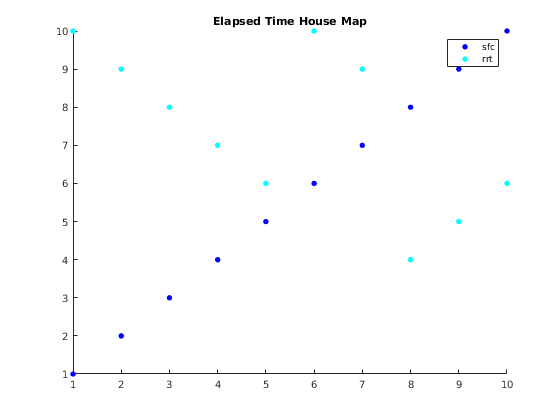


%Figure 2: Elapsed Time House Map
scatter(iterations,time_elapsed_sfc_grid2, "blue", "filled")
hold on;
scatter(iterations,time_elapsed_rrt_grid2, "cyan", "filled")
title ("Elapsed Time House Map")
legend('sfc', 'rrt');

hold off;

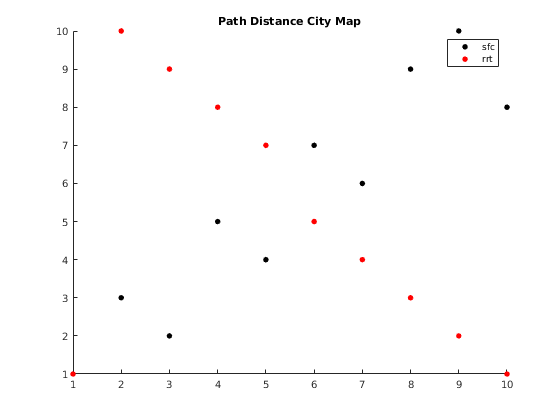


%Figure 3: Path Distance City Map
scatter(iterations,path_distance_sfc_grid1, "black", "filled")
hold on;
scatter(iterations,path_distance_rrt_grid1, "red", "filled")
title ("Path Distance City Map")
legend('sfc', 'rrt');

hold off;

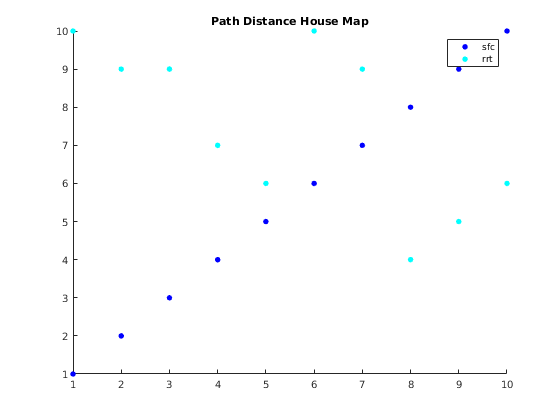


%Figure 4: Path Distance House Map
scatter(iterations,path_distance_sfc_grid2, "blue", "filled")
hold on;
scatter(iterations,path_distance_rrt_grid2, "cyan", "filled")
title ("Path Distance House Map")
legend('sfc', 'rrt');

hold off;

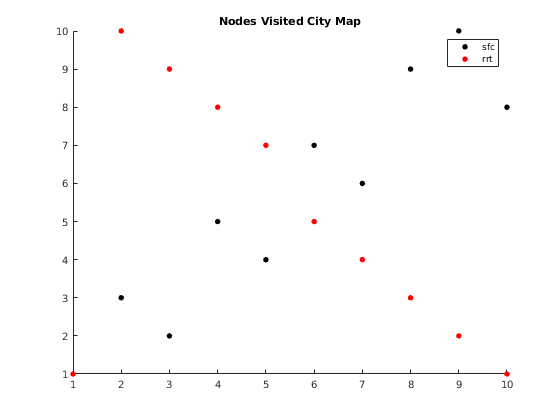


%Figure 5: Nodes Visited City Map
scatter(iterations,nodes_visited_sfc_grid1, "black", "filled")
hold on;
scatter(iterations,nodes_visited_rrt_grid1, "red", "filled")
title ("Nodes Visited City Map")
legend('sfc', 'rrt');

hold off;

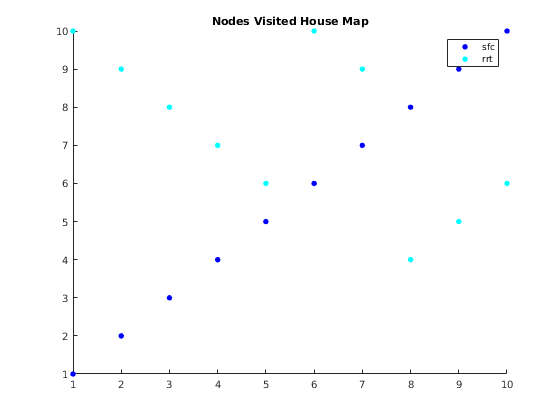


%Figure 6: Nodes Visited House Map
scatter(iterations,nodes_visited_sfc_grid2, "blue", "filled")
hold on;
scatter(iterations,nodes_visited_rrt_grid2, "cyan", "filled")
title ("Nodes Visited House Map")
legend('sfc', 'rrt');

hold off;

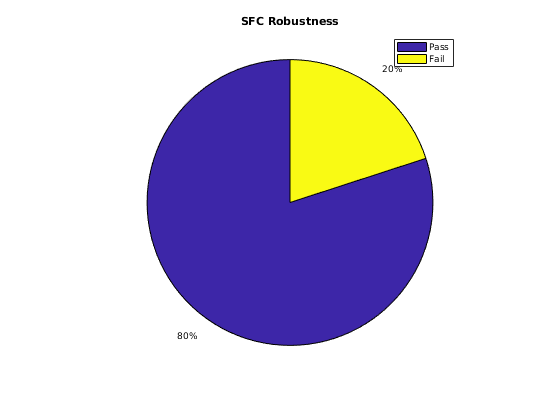


%Figure 7: Robustness SFC on both maps
labels = {'Pass','Fail'};
pie([sfc_pass, sfc_fail])
title ("SFC Robustness")
legend(labels)

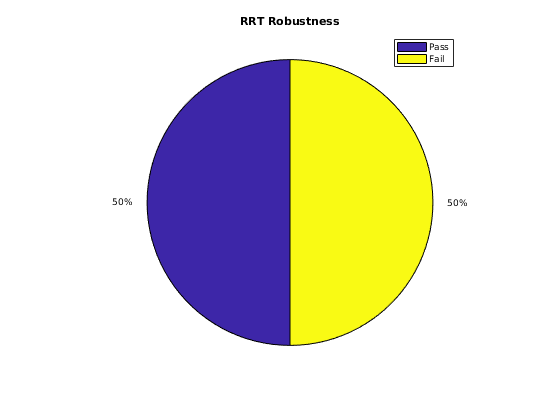


%Figure 7: Robustness RRT on both maps
labels = {'Pass','Fail'};
pie([rrt_pass, rrt_fail])
title ("RRT Robustness")
legend(labels)

### Custom Functions